本code是为了讨论对焦对重构的影响

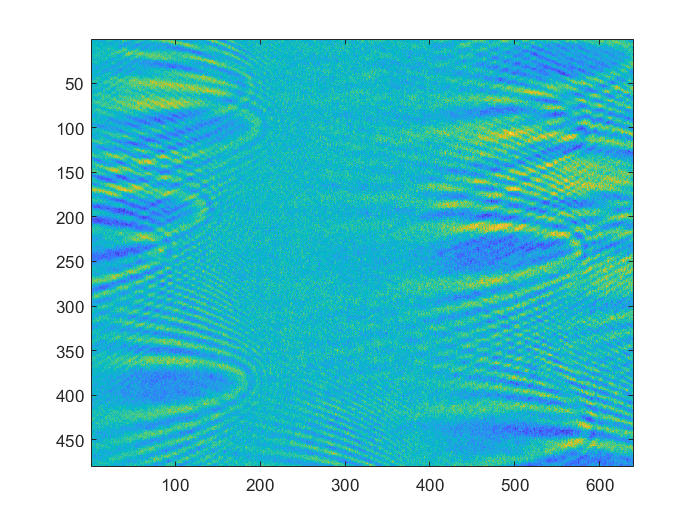

close all
clear all
clc
tiffpath = 'D:\work\散射场\实验数据\20220317_300nmPsNPs_colission_Focus\FOCUS\A5';
tiffs = dir(fullfile(tiffpath,'*.tiff'));
N = length(tiffs);

I = double(imread(fullfile(tiffpath,tiffs(2).name))) -...
    double(imread(fullfile(tiffpath,tiffs(1).name)));
figure
imagesc(I)

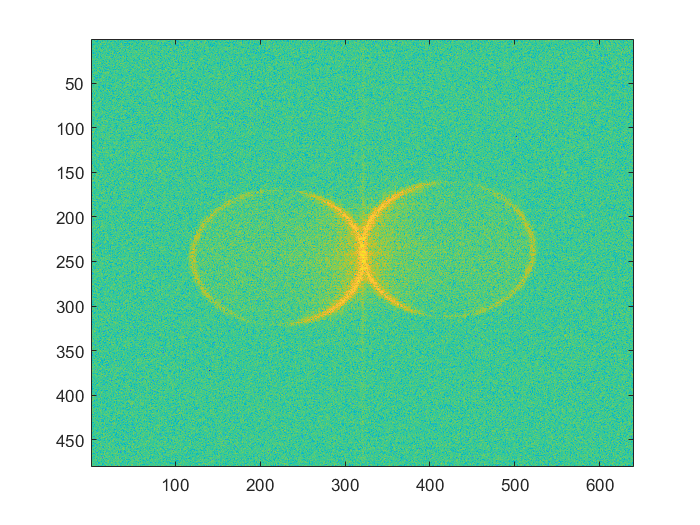

figure
F = fftshift(fft2(I));
figure
imagesc(log(abs(F)))

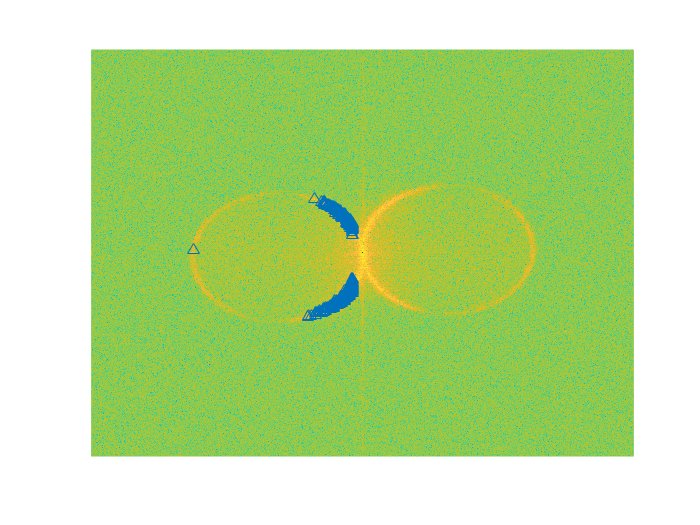

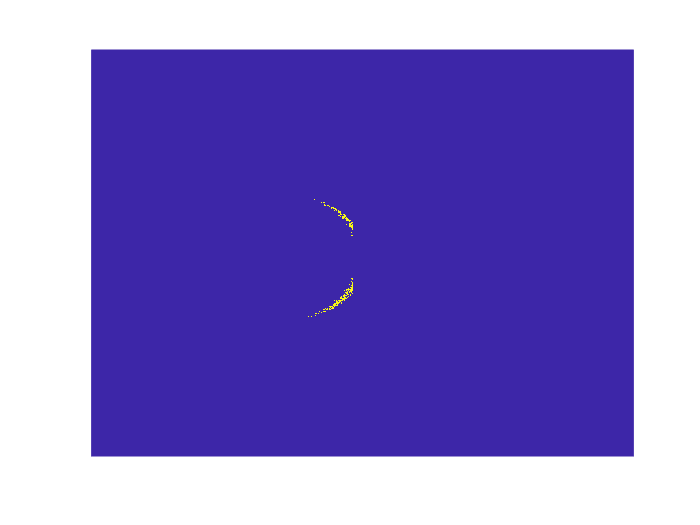

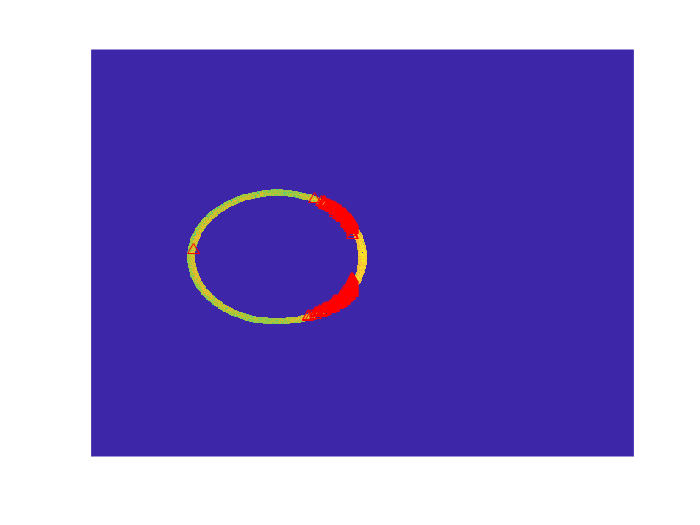

[center_raw,center_col,R,~] = findcircle(log(abs(F)),5,0,1);

peaks = [center_col,center_raw,R];

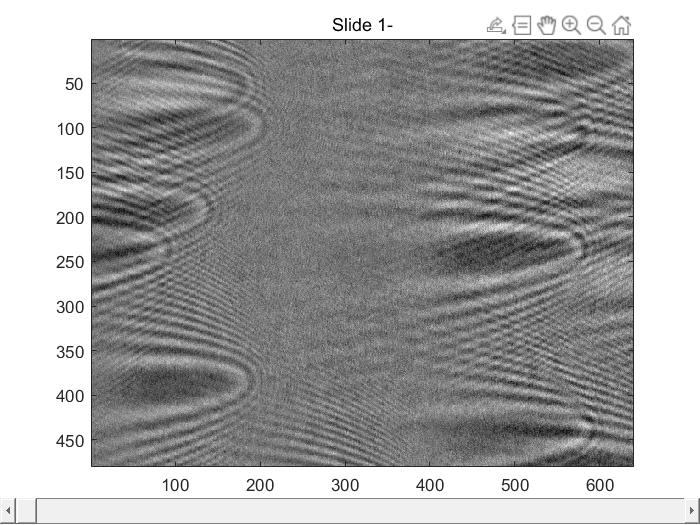

mask = EwaldMask(F,peaks,0.15,'G',2);
I_rcn = zeros([size(mask) round(N/2)]);
I_spr = I_rcn;
for ii = 1:round(N/2)
    I = double(imread(fullfile(tiffpath,tiffs(2*ii).name))) -...
    double(imread(fullfile(tiffpath,tiffs(2*ii - 1).name)));
    F = fftshift(fft2(I));
    I_rcn(:,:,ii) = abs(ifft2(ifftshift(F.*mask)));
    I_spr(:,:,ii) = I;
end
showSlide(I_spr);

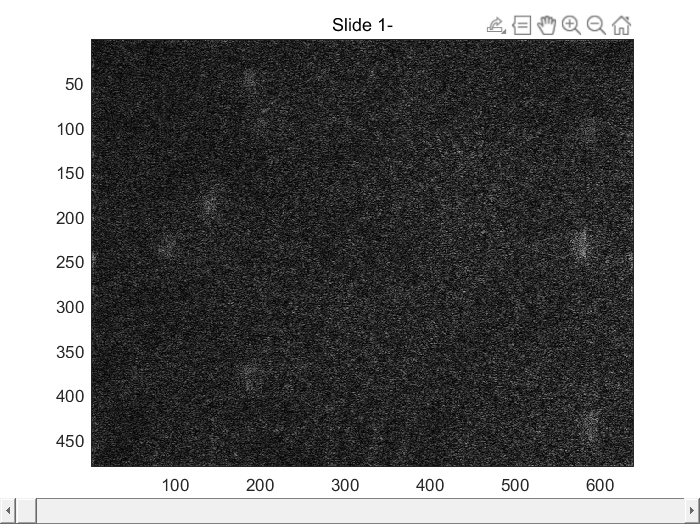

figure
showSlide(I_rcn);

设计截取视野

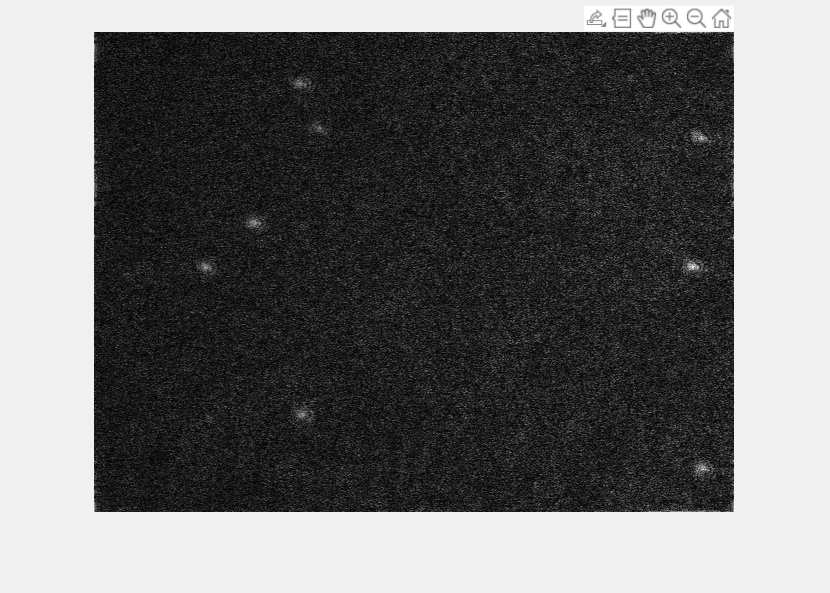

ii = 9;
temp = squeeze(I_rcn(:,:,ii));
temp = normalization(temp);
[~,rectout] = imcrop(temp);

## 挑数据作图

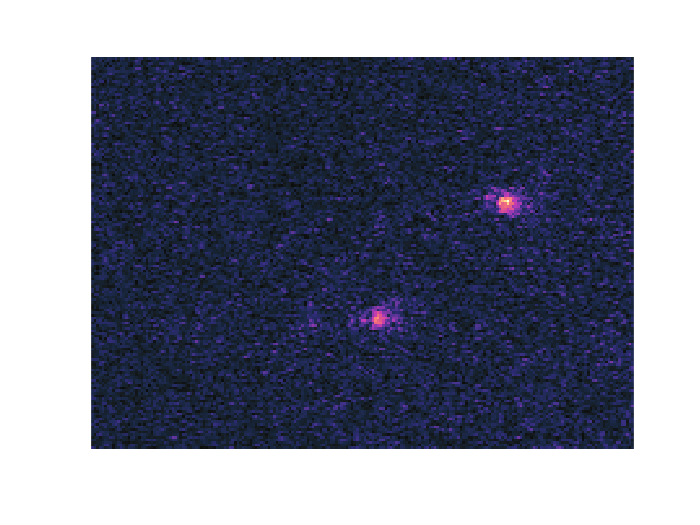

ii = 13;
figure
imagesc(imcrop(squeeze(I_rcn(:,:,ii)),rectout));
axis off
axis equal
colormap(sunglow)

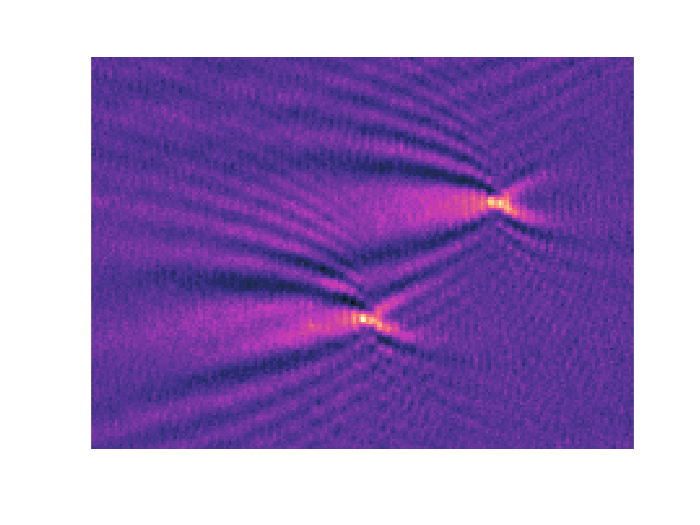

figure
imagesc((-1)^ii*imcrop(squeeze(I_spr(:,:,ii)),rectout));
axis off
axis equal
colormap(sunglow)

## 定义归一化函数

function norml_I = normalization(I)
    max_num = max(I(:));
    min_num = min(I(:));
    norml_I = (I - min_num)/(max_num - min_num);
end